# Simulate Safe Landing of UAV in Unexplored Environment Using Unreal Engine

This example shows how to simulate the safe landing operation of an unmanned aerial vehicle (UAV) in an unexplored environment using Unreal Engine®. In this example, you use lidar sensor data to create a map of the unexplored environment and determine the safe landing area for a multirotor UAV.

Safe landing operation consists of the following operation modes.

- Mission Mode — UAV flies on the flight path  specified by the mission waypoints.

- Emergency Mode — UAV creates a map of the environment from the point cloud data from the sensor.

- Hover and Detect Mode — UAV hovers and uses the map to find a safe landing zone.

- Land Mode — Once a safe landing zone is determined, the UAV lands in that area.

Follow these steps to simulate safe landing operation.

- Specify the UAV mission waypoints in the Simulink model. 

- Interface the Simulink model with the Suburban scene in Unreal Engine®. 

- Add a UAV with a lidar sensor.

- Specify the time of the emergency.

- Run the Simulink model. 

## Model Overview

`uavSafeLanding.slx` consists of the following subsystems.

- Safe Landing Stateflow Chart — Implements the different operation modes of the safe landing operation using a Stateflow chart.

- 3D Simulation Environment — Renders the 3D simulation environment using Unreal Engine®.

- 3D Lidar Sensor — Simulates a lidar sensor in a 3D simulation environment rendered using Unreal Engine®.

- Plant + Controller — Simulates the UAV plant model and position controller.

Open the Simulink model.

open_system("uavSafeLanding.slx") 

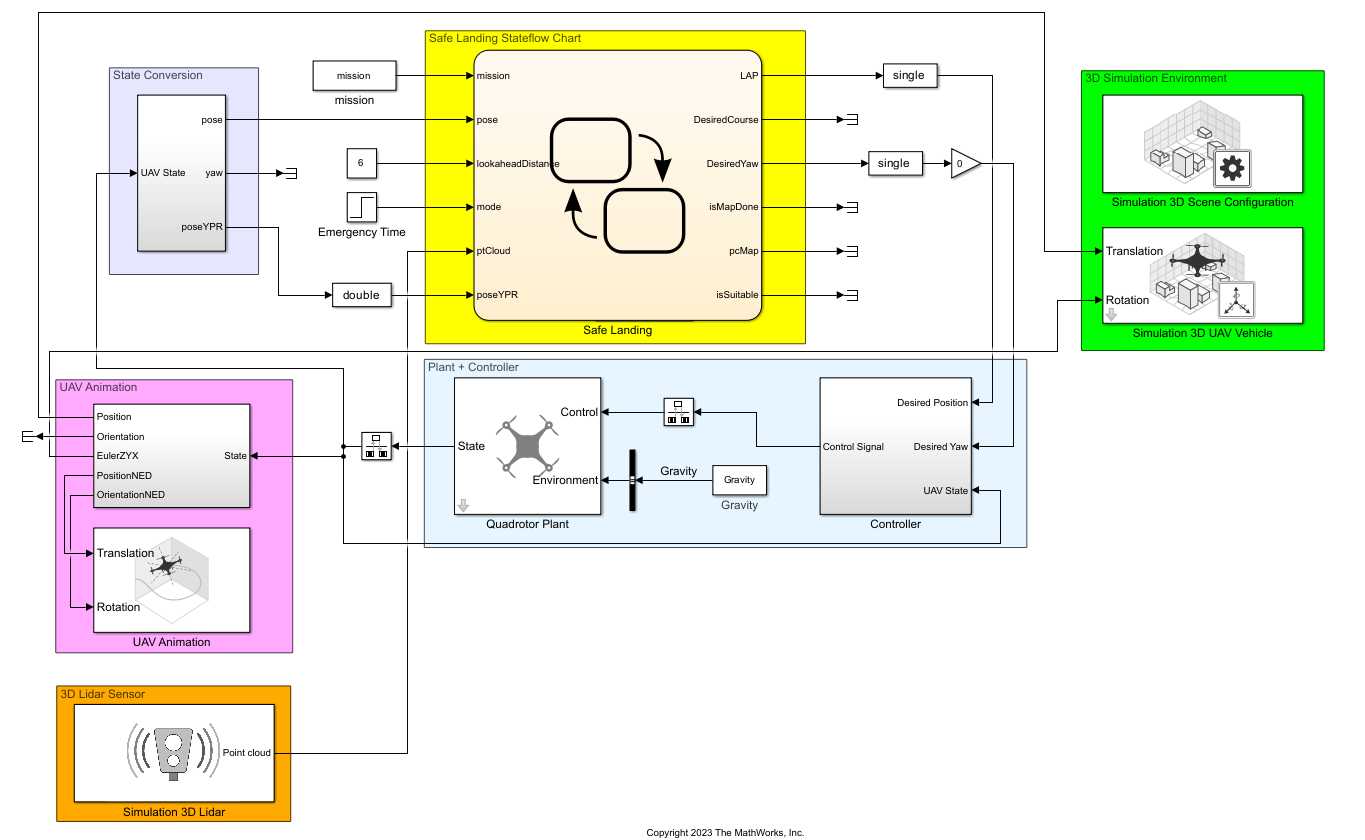

Set the time in seconds in which emergency mode is triggered by specifying the **Emergency time (s)** parameter in the Emergency Time block.

###                            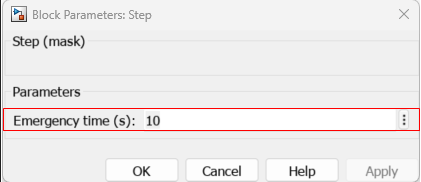

### Safe Landing Stateflow Chart

The safe landing stateflow implements the different modes of the safe landing workflow using a stateflow diagram. 

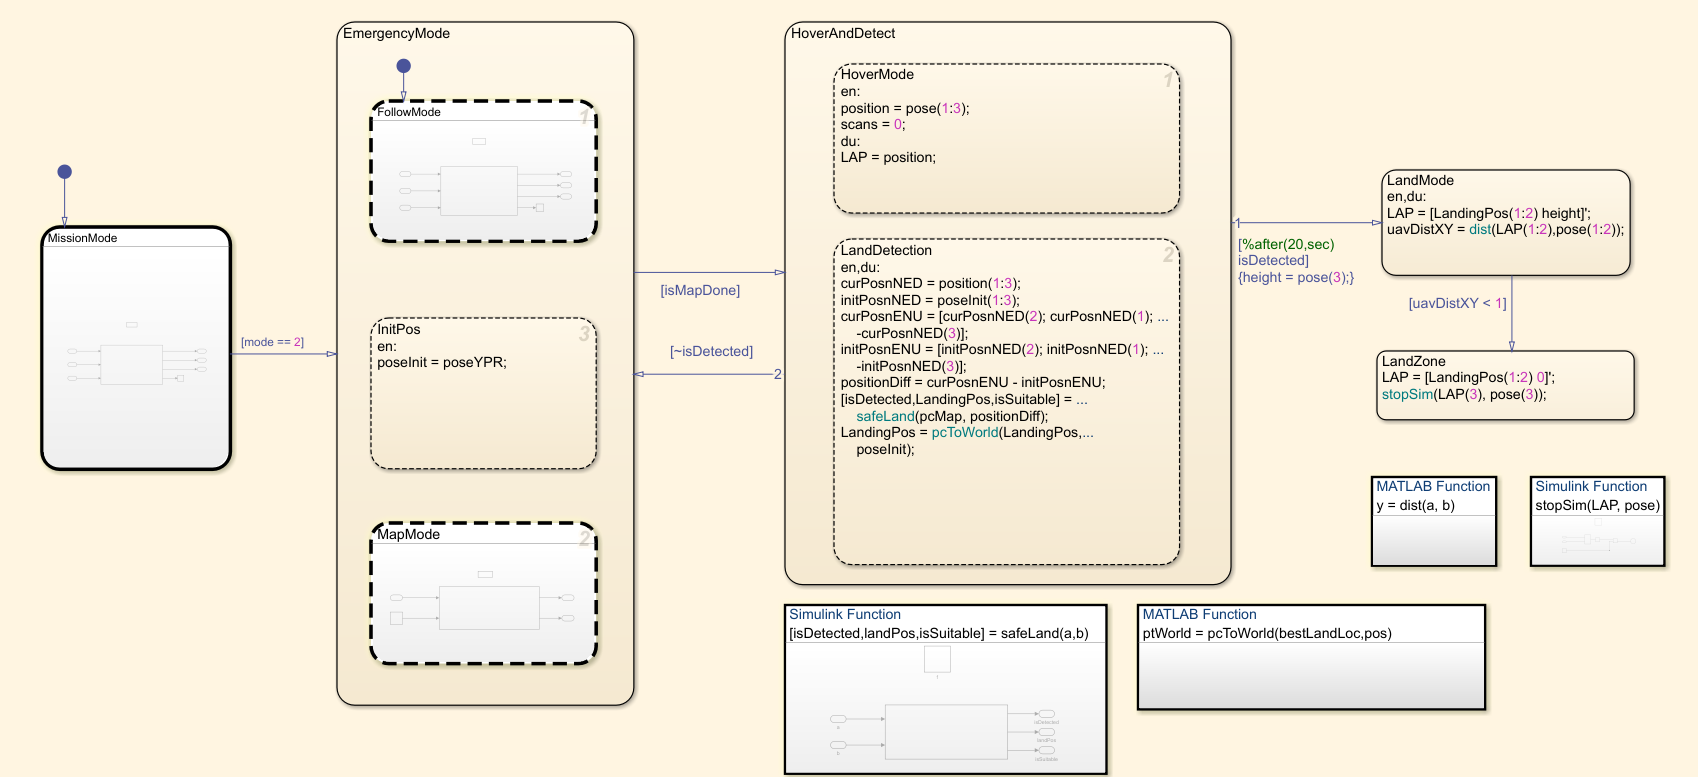

When you activate Mission Mode, the [Waypoint Follower](docid:uav_ref#mw_39443a5e-bef5-4e50-a65d-51ddbdf4b243) block computes the desired position and desired yaw angle to guide the UAV to follow the mission waypoints. When you activate Emergency Mode, the UAV builds a map of the environment from the readings captured by the lidar sensor. After collecting the specified number of scans, the UAV detects the safe landing zone in Hover And Detect mode. Then, the UAV enters Land Mode to descend to the determined landing zone.

These maps, constructed from lidar scans, show the positions of the UAV (red dot) and the safe landing zone (green dot).

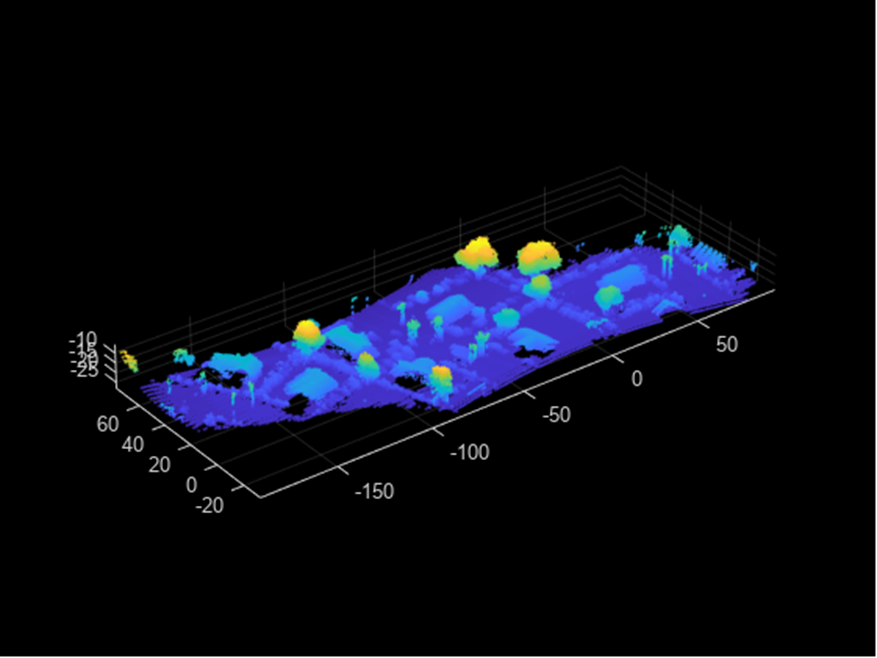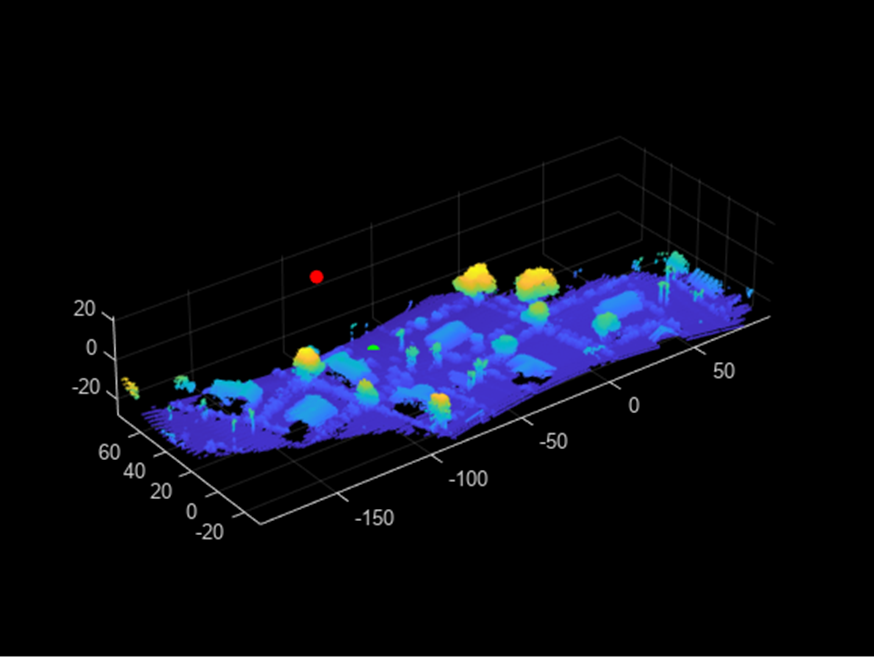

For more information on detecting a safe landing zone from lidar data, see [Determine Safe Landing Area for Aerial Vehicles](matlab:open('..\lidar-ex34296127\DetermineSafeLandingAreaforAerialVehiclesExample.mlx')).

### 3D Simulation Environment

This subsystem configures the scene and UAV in an Unreal Engine® environment. Download the Suburban scene from the `sim3d.maps.Map.Server` and configure the [Simulation 3D Scene Configuration](docid:uav_ref#mw_96a521fd-316f-497b-bc01-b2c5f4083563) block. Select the quadrotor vehicle in the [Simulation 3D UAV Vehicle](docid:uav_ref#mw_619937da-a01b-431e-88b5-4f39caf0b95a) block. For more details on configuring this subsystem, see [Simulate Simple Flight Scenario Using Suburban Scene Map in Unreal Engine Environment](matlab:open('..\uav-ex59349382\SimulateFlightScenarioUsingSuburbanSceneInUnrealEngineExample.mlx')) example.

sim3d.maps.Map.server;

        MapName                        Description                    Version
    ________________    __________________________________________    _______

    "Suburban scene"    "a suburban area beyond the city's border"      "1"  




sim3d.maps.Map.download("Suburban scene");


Map is successfully downloaded and is up-to-date


sim3d.maps.Map.local;

        MapName                        Description                    Version
    ________________    __________________________________________    _______

    "Suburban scene"    "a suburban area beyond the city's border"      "1"  




set_param("uavSafeLanding/Simulation 3D Scene Configuration","SceneDesc","Suburban scene");

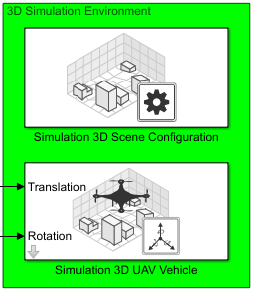 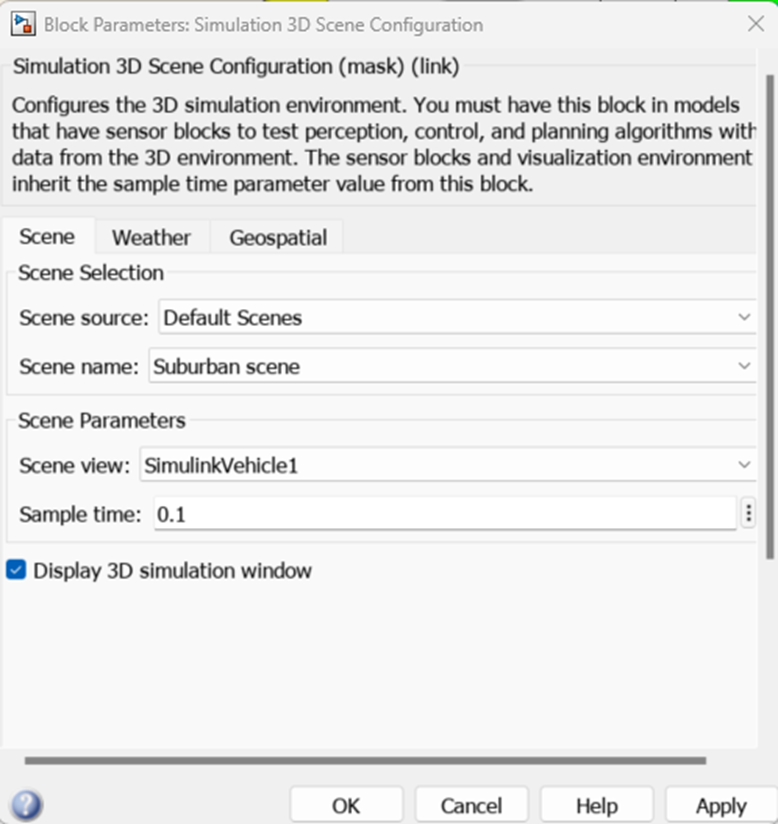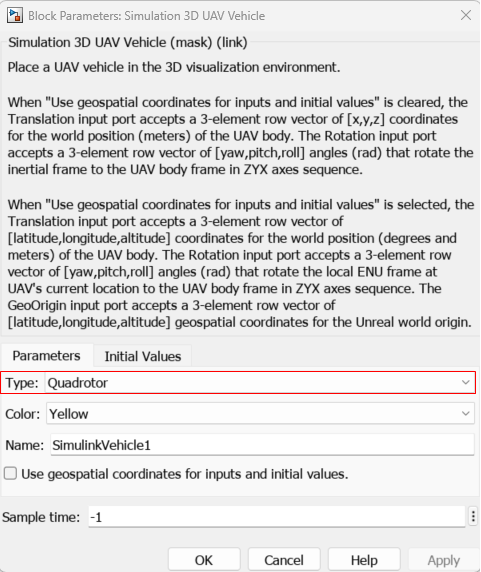

### 3D Lidar Sensor

Use this block to mount the lidar sensor to the UAV and set its parameters. 

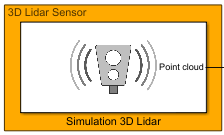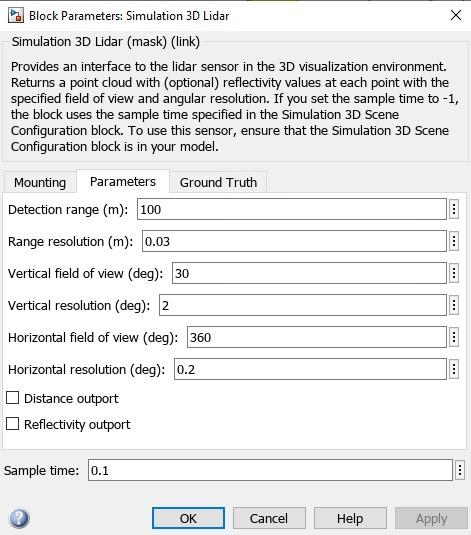

### Plant + Controller

The Plant + Controller subsystem computes the control commands (roll, pitch, yaw rate, and thrust) to the UAV and the states based on the desired position. The controller consists of an outer position controller and an inner attitude controller.

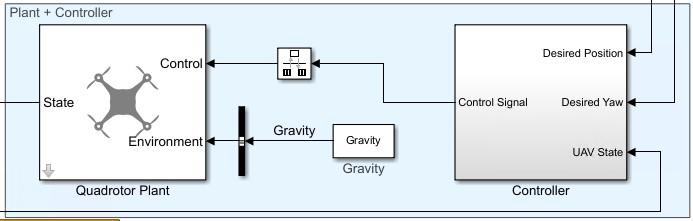

## Simulate Safe Landing of UAV

Specify the mission waypoints in the NED frame. The UAV takes off from the first waypoint, moves in a straight line, and lands at the last waypoint.

mission = [41 15.3 0;41 15.3 -50;100 -100 -50;100 -100 0];


Start the simulation.

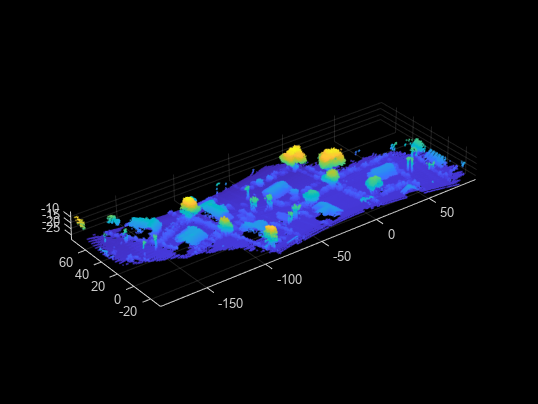

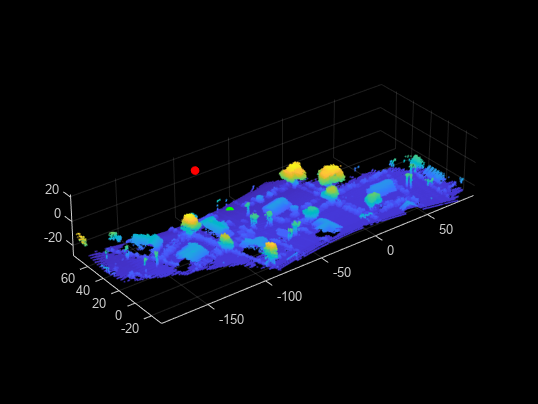

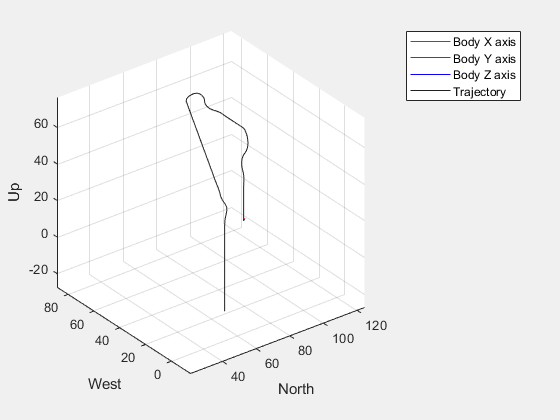

sim("uavSafeLanding.slx");

## Conclusion

This example demonstrates the implementation of a safe landing operation for a multirotor UAV. A map of an unexplored environment in Unreal Engine® is constructed using lidar sensor data, and a safe landing area is determined. This example also shows how you can implement the different modes of the safe landing operation using Simulink stateflow.    

*Copyright 2023 The MathWorks, Inc.*